ZIE MM MATLAB kurzus

# Tömb műveletek

## Témák:

- tömb műveletek

- indexelés

- logikai indexelés

- módosítás

- műveletek

- függvények

clc; clear; close all;

## Tömb műveletek (array operations)

### Indexelés (indexing)

Tömbök kezelésénél az egyik alap funkció az elemek kinyerése. Ennek legegyszerább módszere az elemek index szerinti kiolvasása. Sok programnyelvvel ellentétben MATLAB-ban a tömbök indexelése 1-től kezdődik (vallási vitákba ennek helyességéről nem bocsátkozunk).

[https://www.cs.utexas.edu/~EWD/transcriptions/EWD08xx/EWD831.html](https://www.cs.utexas.edu/~EWD/transcriptions/EWD08xx/EWD831.html)

[https://youtu.be/0uQ3bkiW5SE?si=OCvcqyAbOJ3CmAfl](https://youtu.be/0uQ3bkiW5SE?si=OCvcqyAbOJ3CmAfl)

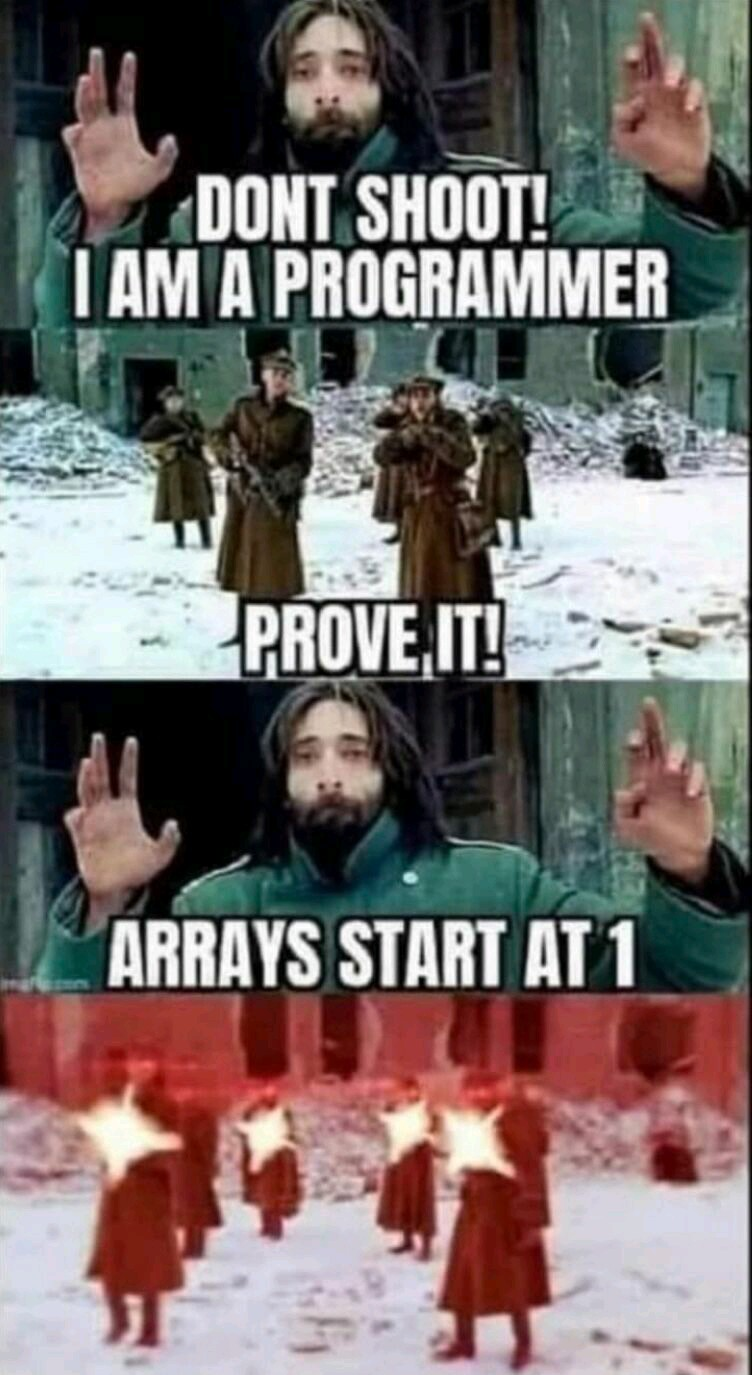

Indexelési példák vektorokra:

d(1) % első elem
d(end) % utolsó elem
d(end-1) % utolsó előtti elem

Lehetőség van egyszerre több elemet is kiválogatni (array slicing):

d(1:3) % elemek 1-től 3-ig
d([1,2,3]) % 1-es, 2-es és 3-as elemek
d(2:2:end) % minden második elem
d(end:-1:1) % sorrend megfordítása

Több dimenziós tömbök (pl.: mátrixok) esetén az összes dimenzióban meg kell adni az indexet:

j = [1:3;4:6;7:9]
j(1,2) % 1. sor, 2. oszlop
j(1,:) % 1. sor minden oszlopa
j(:,1) % minden sor 1. oszlopa
j(1:2,[1,3]) % 1. és 2. sorok, 1. és 3. oszlopai
j(4) % lineáris indexelés, mintha az oszlopok egymás után lennének téve

Értékek felülírása:

j(1,:) = 0 % 1. sor nullázása
j([2,3],3) = [66,99] % 2. és 3. sorok utolsó oszlopának lecserélése

### Logikai indexelés (logical indexing)

A sorszám szerinti hivatkozás helyett használható az úgy nevezett logikai indexelés is. Ekkor ahelyett, hogy a szükséges értékek indexe kerülne megadásra, egy a tömbbel megegyező dimenziójú logikai tömb IGAZ-HAMIS értékei szerint kerülnek leválogatásra az értékek.

Logikai indexelésre használható logikai tömbök legkönnyebben az eredeti tömbön végzett relációs művelettel kaphatók.

k = [1:4;5:8;9:12;13:16]
l = k > 3 % logikai mátrix
k(l) % leválogatás
k(k > 3) % összevonva
k(logical(eye(4))) % átló értékek kinyerése egység mátrixxal
k(mod(k,2)==0) = -k(mod(k,2)==0) % 2-vel oszthatók negálása

### Matematikai műveletek

Sok programnyelvben nincs beépített mátrix adattípus, így mátrix műveleteket csak tömbökön futtatott ciklusokkal lehet végrahajtani.

Ciklusos mátrix-skalár szorzás fapados példa:

m = [1:3;4:6;7:9]
n = m;
o = 221;
p = size(m)
for row = 1:p(1) % soronként
    for col = 1:p(2) % minden oszlop
        n(row,col) = n(row,col) * o; % felülírás
    end
end
n

Ciklusos mátrix-mátrix szorzás fapados példa:

q = zeros(p);
for row = 1:p(1)
    for col = 1:p(2)
        value = 0;
        for idx = 1:p(1)
            value = value + m(row,idx)*m(idx,col);
        end
        q(row,col) = value;
    end
end
q

Beépített mátrix műveletekkel ugyan ezek:

m * o % skalár szorzás
m * m % mátrix szorzás

Műveletek különböző dimenziójú tömbökkel:

r = (11:13)'
m * r % mátrix szorzás
m .* r % soronkénti szorzás
m .* r' % oszloponkéntti szorzás

Fontosabb függvények:

s = [[1,6,2];[76,2,5];[44,21,653]]
det(s) % determináns
inv(s) % inverz
s^-1 % inverz hatványozással
pinv(s) % Moore-Penrose pszeudo inverz
diag(s) % átló
svd(s) % szinguláris érték felbontás
[t,u] = eig(s) % saját érték, saját vektor (eigenvalues, eigenvectors)